eulerd=[90,90,90];
angleX=eulerd(1)/180*pi;
angleY=eulerd(2)/180*pi;
angleZ=eulerd(3)/180*pi;
% syms angleZ angleY angleX x y z
Rz=[cos(angleZ) -sin(angleZ) 0;sin(angleZ) cos(angleZ) 0;0 0 1];
Ry=[cos(angleY) 0 sin(angleY);0 1 0;-sin(angleY) 0 cos(angleY)];
Rx=[1 0 0; 0 cos(angleX) -sin(angleX); 0 sin(angleX) cos(angleX)];
%Pw=R(z)Pz=R(z)R(y)Py=R(z)R(y)R(x)Px
R=(Rz*Ry*Rx);  %R是Twc
%由欧拉角转四元数和旋转矩阵
q=angle2quat(angleZ,angleY,angleX,'ZYX');
R=angle2dcm(0,0,1,'ZYX')

R =                          1                         0                         0
                         0          0.54030230586814         0.841470984807897
                         0        -0.841470984807897          0.54030230586814


makehgtform('xrotate',1)

ans =                          1                         0                         0                         0
                         0          0.54030230586814        -0.841470984807897                         0
                         0         0.841470984807897          0.54030230586814                         0
                         0                         0                         0                         1


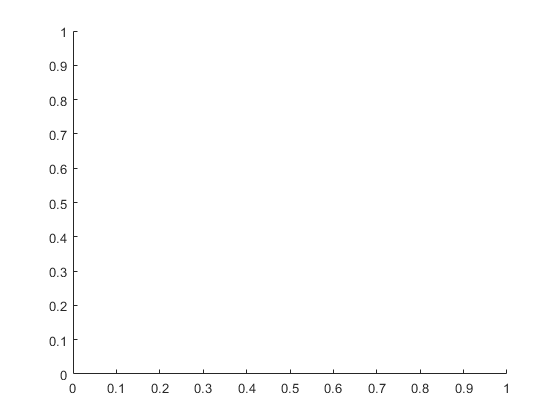

错误使用  * 
用于矩阵乘法的维度不正确。请检查并确保第一个矩阵中的列数与第二个矩阵中的行数匹配。要执行按元素相乘，请使用 '.*'。

axis*R

%由四元数转欧拉角和旋转矩阵
[angleZ angleY angleX]=quat2angle(q,'ZYX');
R=quat2dcm(q);
%由旋转矩阵转欧拉角和四元数
[angleZ angleY angleX]=dcm2angle(R,'ZYX');
q=dcm2quat(R);

%%matlab自带位姿变换矩阵
%注意，这里的旋转矩阵乘以一个向量得到的值，还是在当前坐标系下
M = makehgtform('translate',[1 1 1]);
M = makehgtform('xrotate',angleX)*makehgtform('yrotate',angleY)*makehgtform('zrotate',angleZ);
makehgtform('xrotate',angleX);
makehgtform('yrotate',angleY);
makehgtform('zrotate',angleZ);
%%四元数的乘法
eulerd=[20,10,15];
angleX=eulerd(1)/180*pi;
angleY=eulerd(2)/180*pi;
angleZ=eulerd(3)/180*pi;
%由欧拉角转四元数和旋转矩阵
deltaq=angle2quat(angleZ,angleY,angleX,'ZYX');
%四元数求逆
invq=quatinv(deltaq);
%四元数乘法
mul=quatmultiply(q,deltaq);%顺序是先旋转q，再旋转deltaq
R=quat2dcm(mul);
R=quat2dcm(deltaq)*quat2dcm(q);
